# Praktikum 2: Aufgabe 1

% f: die zu minimierende Funktion f(x)
% df: Ableitung der Funktion, f'(x)
[f, df] = createFuncsA1();

## Plotten der Funktion

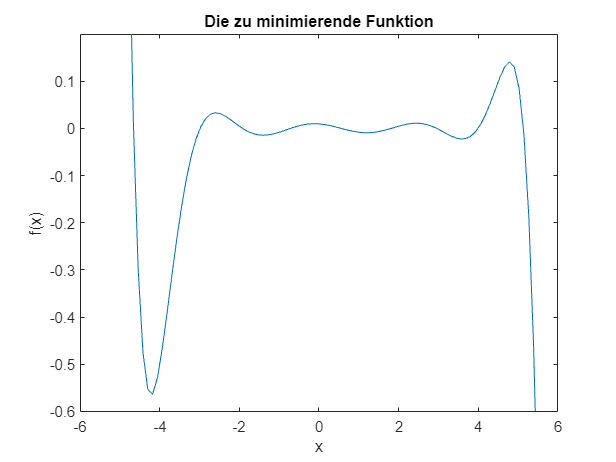

xx = linspace(-6, 6);
plot(xx, f(xx));
ylim([-0.6, 0.2]);
xlabel('x'), ylabel('f(x)'), title('Die zu minimierende Funktion');

## Gradientenabstieg


% Find the best hyper parameters for a gradient descent algorithm using RMSProp
% beta: the parameter beta
% eta: the parameter eta
% iter: the number of iterations
% x0: the starting point
% track: the track of the algorithm
% epsilon: the parameter epsilon



% Anfangswerte
x0 = 4.7;   % Anfangspunkt, nicht ändern!

% Hyperparameter
iter = 1000;
epsilon = 10^-8;

% Speicher für die Ergebnisse

beta = 0.9;
step_size = 0;
eta = 0.4;
s = 0;

% RMSProp
[w, track] = gaRmsProp(df, eta, x0, iter, beta);
w

w = 3.7451

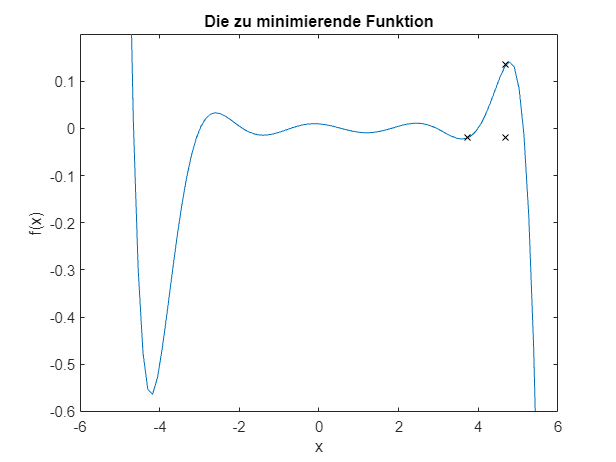

% for ii = 1:iter
%     s(ii+1) = s(ii) * beta + (1-beta) * df(x0(ii)) * df(x0(ii));
%     step_size(ii+1) = eta/sqrt(s(ii+1) + epsilon);
%     x0(ii+1) = x0(ii) - step_size(ii+1) * df(x0(ii));
% end
% track(end+1) = x0(end);

hold on
plot(w, f(w), '--kx')
hold off